# 半参数模型

## 简介

**参数部分：**

以欧拉-牛顿动力学方程的矩阵形式为基础，在此基础上进行改进：

- 修改并优化了摩擦力模型；

- 添加了物理学约束；

- 使用了fmincon方法优化出参数；

**非参数部分：**

以LSTM网络为基础，对摩擦力的非线性部分进行拟合。

## 代码-参数部分：

### 加载数据与设置参数

addpath '.\semi-parameters'
warning off; clear; clc; config;

### 计算回归矩阵

[n_sample, ~] = size(q_filt);
n_parameters = 43;
ww = zeros(n_sample * 7, n_parameters);

for k = 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);

    start_row = 1 + (k - 1) * 7;
    end_row = k * 7;

    ww(start_row : end_row, :) = compute_regression_matrix(q, qd, qdd, 0);
end

### 计算参数部分的辨识力矩

n_parameters = 126;
T_idy = compute_identified_torque_with_Stribeck_model(opt_x);
T_idy = reshape(T_idy, 7, []);
T_idy = T_idy';

## 代码-非参数部分：

工作流程如下：

- 制作数据集；

- 划分数据集 & 转换格式；

- 搭建LSTM神经网络；

- 训练神经网络；

- 验证神经网络；

- 验证模型效果；

### 第一步：制作数据集

num_sample_point = size(q_filt, 1);
database = zeros(num_factors * size(Joint, 1) + 1, num_sample_point);  % 加1是因为时间只有一个维度；
error_from_parameters_model = t_filt - T_idy;

for frame = 1 : num_sample_point
   database(:, frame) = [q_filt(frame, :)'; qd_filt(frame, :)'; qdd_filt(frame, :)'; t_filt(frame, :)'; frame * sample_period; error_from_parameters_model(frame, :)'];
end

### 第二步：划分数据集 & 转换格式

% 划分数据集
split = floor(num_sample_point * train_percent);
INPUT_TRAIN = database(1 : (num_factors - 1) * size(Joint, 1) + 1, 1 : split);
output_train = database((num_factors - 1) * size(Joint, 1) + 2 : end, 1 : split);
INPUT_TEST = database(1 : (num_factors - 1) * size(Joint, 1) + 1, split + 1 : end);
output_test = database((num_factors - 1) * size(Joint, 1) + 2 : end, split + 1 : end);

% 格式转换
input_train = cell(1, size(INPUT_TRAIN, 2));
input_test = cell(1, size(INPUT_TEST, 2));

for i = 1 : size(INPUT_TRAIN, 2)
    input_train{1, i} = INPUT_TRAIN(:, i);
end

for i = 1 : size(INPUT_TEST, 2)
    input_test{1, i} = INPUT_TEST(:, i);
end


### 第三步：定义LSTM神经网络

layers = [
    sequenceInputLayer((num_factors - 1) * size(Joint, 1) + 1)    % 建立输入层
    
    lstmLayer(32, 'OutputMode', 'last')                           % LSTM层
    reluLayer                                                     % Relu激活层

    lstmLayer(16, 'OutputMode', 'last')                           % LSTM层
    reluLayer                                                     % Relu激活层

    lstmLayer(8, 'OutputMode', 'last')                            % LSTM层
    reluLayer                                                     % Relu激活层

    fullyConnectedLayer(7)                                        % 全连接层
    regressionLayer                                               % 回归层
    ];

### LSTM参数设置

options = trainingOptions('adam', ...            % Adam 梯度下降算法
    'MiniBatchSize', BatchSize, ...              % 批大小
    'MaxEpochs', Epochs, ...                     % 最大迭代次数
    'InitialLearnRate', 0.01, ...                % 初始学习率
    'LearnRateSchedule', 'piecewise', ...        % 学习率下降
    'LearnRateDropFactor', 0.5, ...              % 学习率下降因子
    'LearnRateDropPeriod', Epochs * 0.4, ...     % 经过X次训练后，学习率为InitialLearnRate * LearnRateDropFactor
    'Shuffle', 'every-epoch', ...                % 每次训练后训练打乱数据
    'Plots', 'training-progress', ...            % 画出曲线
    'Verbose', false);

### 第四步：训练神经网络

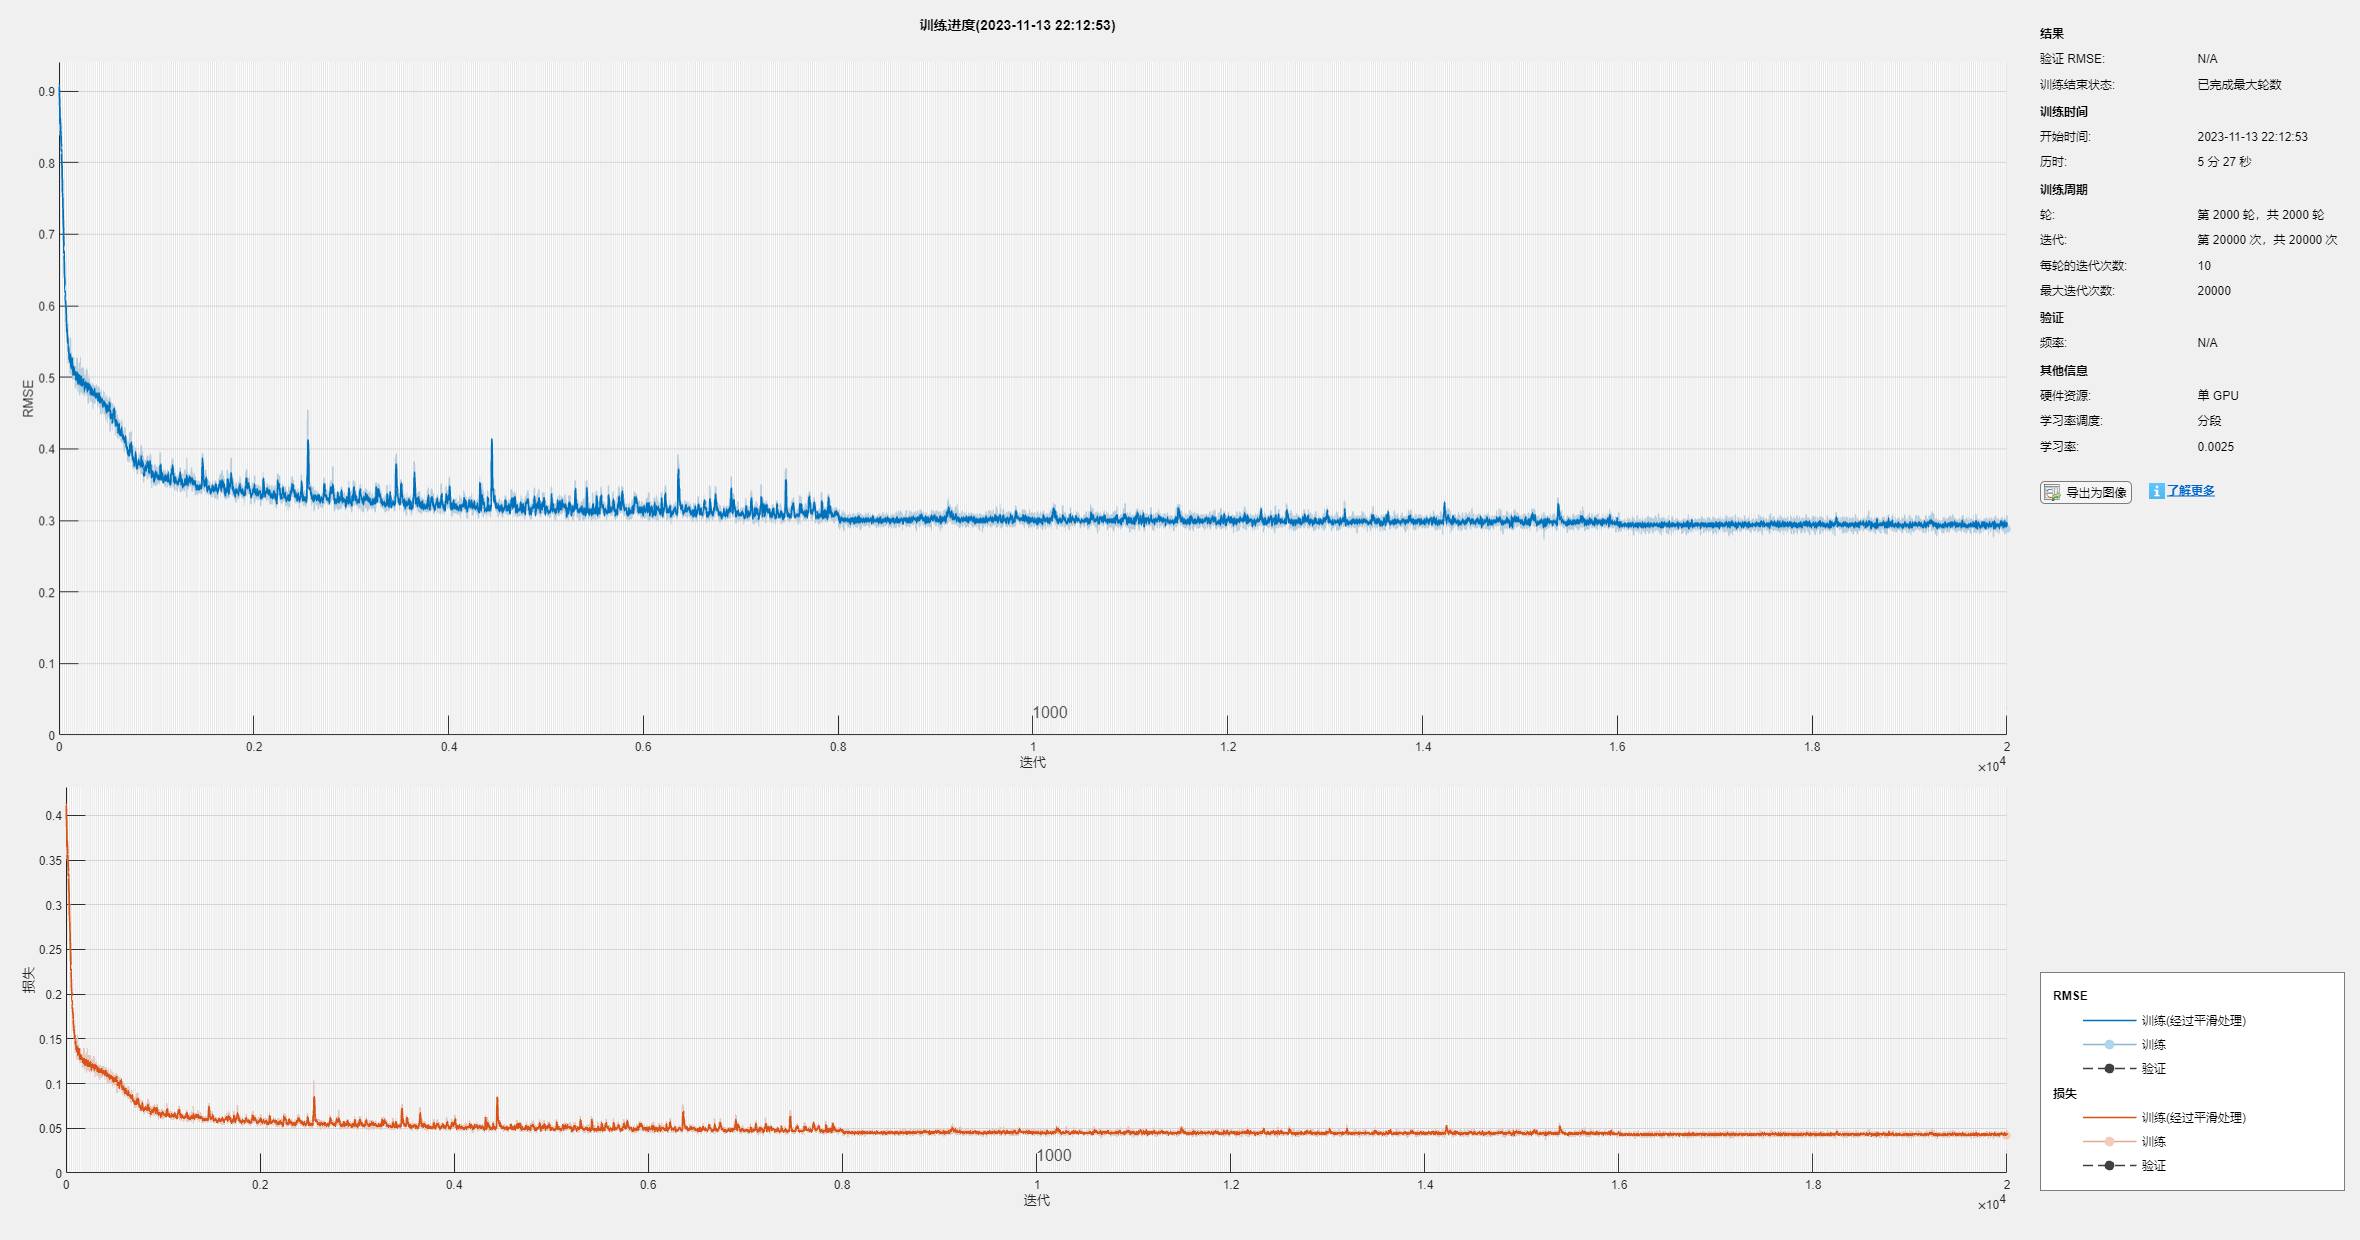

net = trainNetwork(input_train, output_train', layers, options);

### 保存神经网络

save('data\Semi_parameters\net.mat', 'net');
analyzeNetwork(net);

### 第五步：验证神经网络

t_sim1 = predict(net, input_train);
t_sim2 = predict(net, input_test);
t_sim = double([t_sim1; t_sim2]);

% 均方误差
error1 = sqrt(sum((t_sim1' - output_train).^2) ./ size(output_train, 1));
error2 = sqrt(sum(t_sim2' - output_test).^2 ./ size(output_test, 1));

### 画图

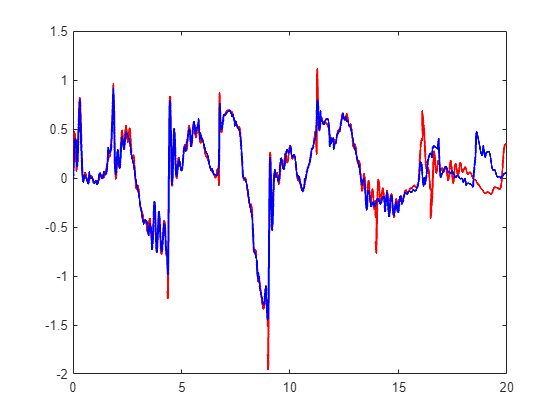

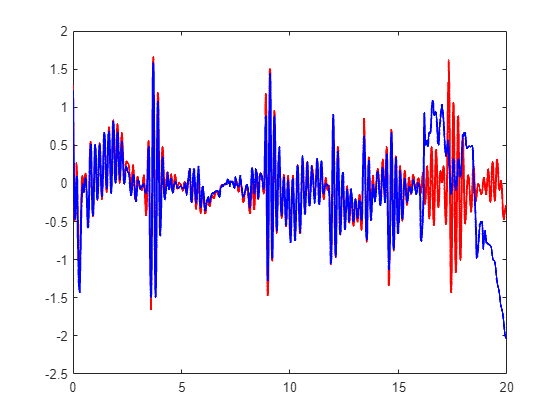

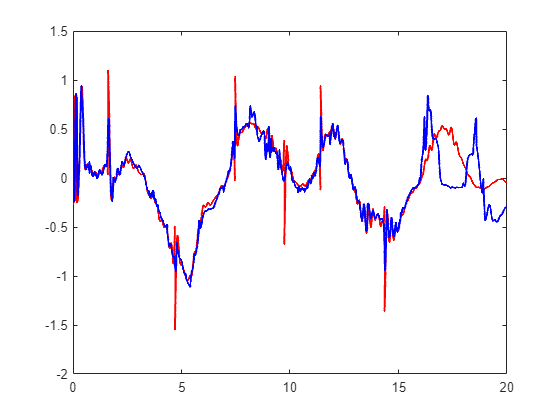

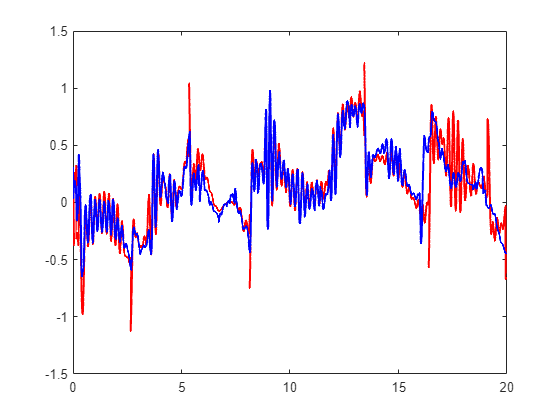

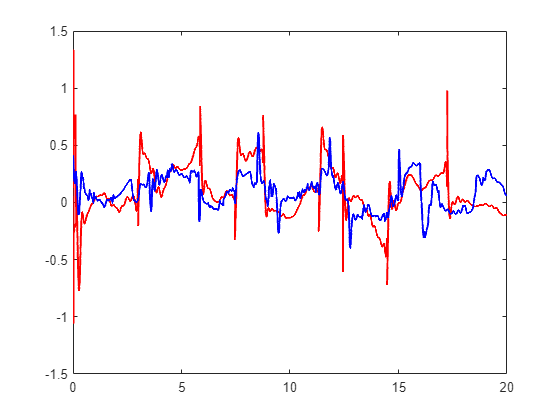

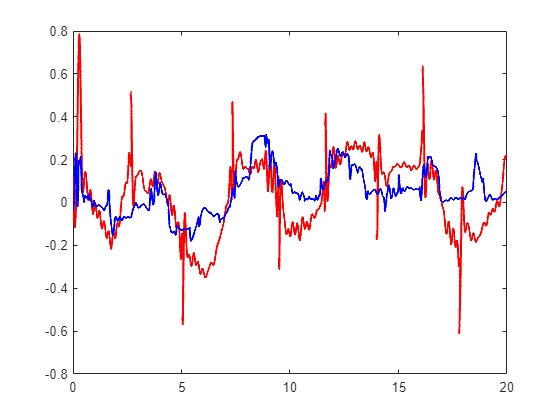

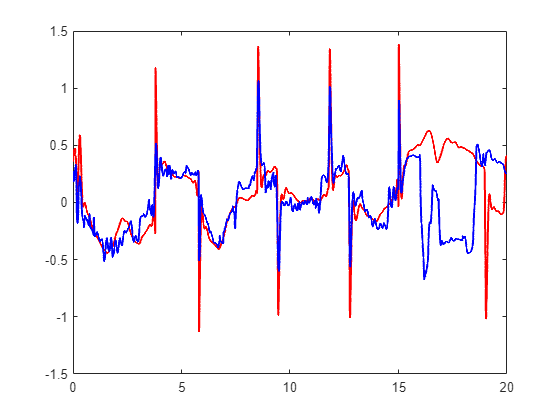

x_axis = linspace(0, 20, sample_frequence * 20 + 1);
for joint = Joint1 : Joint7
    figure;

    plot(x_axis, error_from_parameters_model(:, joint), 'r', 'LineWidth', 1.5); 
    hold on;
    plot(x_axis, t_sim(:, joint), 'b', 'LineWidth', 1.5)
    hold off;
end